#### EX 5-1 离散数学

% 分解质因数
primeFactors = factor(20)

primeFactors =      2     2     5


% 最大公约数
greatestCommonDivisor = gcd(20, 15)

greatestCommonDivisor = 5

% 最小公倍数
leastCommonMultiple = lcm(20, 15)

leastCommonMultiple = 60

% 确定哪些数组元素为质数
isPrime = isprime([2 3 0 6 10])

isPrime = 1×5 logical 数组
   1   1   0   0   0


% 小于等于输入值的质数
PrimeNumbers = primes(20)

PrimeNumbers =      2     3     5     7    11    13    17    19


% 所有可能的排列
permutations = perms([1 2 3])

permutations =      3     2     1
     3     1     2
     2     3     1
     2     1     3
     1     3     2
     1     2     3


% 输入的阶乘
inputFactorial = factorial(5)

inputFactorial = 120

% 有理分式近似值
rationalFraction = rat(pi,1e-7)

rationalFraction = '3 + 1/(7 + 1/(16 + 1/(-294)))'

#### EX 5-2 多项式


$$p\left(x\right)=x^4 -10x^3 +35x^2 -50x+24$$


% 创建上述多项式
p = [1 -10 35 -50 24]

p =      1   -10    35   -50    24


% 计算x为2时多项式的值
polyValue = polyval(p,2.5)

polyValue = 0.5625

% 同时计算x为从1到5时的值
polyValue2 = polyval(p,1:5)

polyValue2 =      0     0     0     0    24


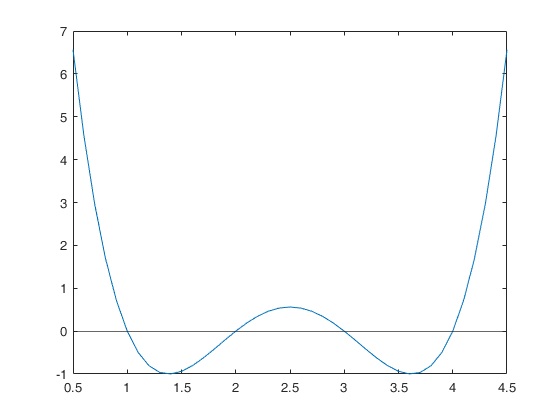

% 多项式作图
x=0.5:0.1:4.5;
plot(x,polyval(p,x)); yline(0);

% 求多项式的根
r = roots(p)

r =     4.0000
    3.0000
    2.0000
    1.0000


% 由根反求多项式
pCalc = poly(r)

pCalc =     1.0000  -10.0000   35.0000  -50.0000   24.0000


% 显示多项式
poly2sym(p)

$$ans = x^{4}-10\,x^{3}+35\,x^{2}-50\,x+24$$

#### EX 5-3 矩阵基本运算

% 准备符号阵和数值阵
syms a b c d
x = [a b; c d]

$$x = \left(\begin{array}{cc} a & b\\ c & d \end{array}\right)$$

y = [1 2; 3 4]

y =      1     2
     3     4


% 对角线向量
diagX = diag(x)

$$diagX = \left(\begin{array}{c} a\\ d \end{array}\right)$$

diagY = diag(y)

diagY =      1
     4


% 由对角线向量构成对角阵
diagMatrixX = diag(diag(x))

$$diagMatrixX = \left(\begin{array}{cc} a & 0\\ 0 & d \end{array}\right)$$

diagMatrixY = diag(diag(y))

diagMatrixY =      1     0
     0     4


% 矩阵的迹
traceX = trace(x)

$$traceX = a+d$$

traceY = trace(y)

traceY = 5

% 矩阵的秩
rankX = rank(x)

rankX = 2

rankY = rank(y)

rankY = 2

% 矩阵的行列式
detX = det(x)

$$detX = a\,d-b\,c$$

detY = det(y)

detY = -2

#### EX 5-3 三角分解与特征分解

% 准备符号阵和数值阵
syms a b c d
x = [a b; c 0]

$$x = \left(\begin{array}{cc} a & b\\ c & 0 \end{array}\right)$$

y = [1 2; 3 0]

y =      1     2
     3     0


1.三角分解


$$\begin{array}{l}
A=L\;U\\
A=P^{\prime } \;L\;U
\end{array}$$


% LU分解
[Lx, Ux] = lu(x)

$$Lx = \left(\begin{array}{cc} 1 & 0\\ \frac{c}{a} & 1 \end{array}\right)$$

$$Ux = \left(\begin{array}{cc} a & b\\ 0 & -\frac{b\,c}{a} \end{array}\right)$$

[Ly, Uy] = lu(y)

Ly =     0.3333    1.0000
    1.0000         0


Uy =      3     0
     0     2


% P'LU分解
[Ly, Uy, Py] = lu(y)

Ly =     1.0000         0
    0.3333    1.0000


Uy =      3     0
     0     2


Py =      0     1
     1     0


2. 特征分解


$$A=V\;D\;V^{-1}$$


[Vx, Dx] = eig(x)

$$Vx = \left(\begin{array}{cc} \frac{\frac{a}{2}-\frac{\sqrt{a^{2}+4\,b\,c}}{2}}{c} & \frac{\frac{a}{2}+\frac{\sqrt{a^{2}+4\,b\,c}}{2}}{c}\\ 1 & 1 \end{array}\right)$$

$$Dx = \left(\begin{array}{cc} \frac{a}{2}-\frac{\sqrt{a^{2}+4\,b\,c}}{2} & 0\\ 0 & \frac{a}{2}+\frac{\sqrt{a^{2}+4\,b\,c}}{2} \end{array}\right)$$

[Vy, Dy] = eig(y)

Vy =     0.7071   -0.5547
    0.7071    0.8321


Dy =      3     0
     0    -2


#### EX 5-4 解线性方程


$$\left\lbrack \begin{array}{cc}
3 & 4\\
2 & 5
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
11\\
12
\end{array}\right\rbrack$$


% 解方程 Ax=b
A = [3 4; 2 5];
b=[11 12]';
% 求解方法一
solve1 = A\b

solve1 =      1
     2


% 求解方法二
inverseA = inv(A)

inverseA =     0.7143   -0.5714
   -0.2857    0.4286


solve2 = inv(A)*b

solve2 =     1.0000
    2.0000



$$\left\lbrack \begin{array}{cc}
a & b\\
c & d
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
e\\
f
\end{array}\right\rbrack$$


% 解方程 Ax=b
syms a b c d e f
A = [a b; c d];
b=[e f]';
solve1 = A\b

$$solve1 = \left(\begin{array}{c} -\frac{b\,\bar{f}-d\,\bar{e}}{a\,d-b\,c}\\ \frac{a\,\bar{f}-c\,\bar{e}}{a\,d-b\,c} \end{array}\right)$$

inverseA = inv(A)

$$inverseA = \left(\begin{array}{cc} \frac{d}{a\,d-b\,c} & -\frac{b}{a\,d-b\,c}\\ -\frac{c}{a\,d-b\,c} & \frac{a}{a\,d-b\,c} \end{array}\right)$$

solve2 = inv(A)*b

$$solve2 = \left(\begin{array}{c} \frac{d\,\bar{e}}{a\,d-b\,c}-\frac{b\,\bar{f}}{a\,d-b\,c}\\ \frac{a\,\bar{f}}{a\,d-b\,c}-\frac{c\,\bar{e}}{a\,d-b\,c} \end{array}\right)$$

% 化简符号表达式
simpSlolve2 = simplify(solve2)

$$simpSlolve2 = \left(\begin{array}{c} -\frac{b\,\bar{f}-d\,\bar{e}}{a\,d-b\,c}\\ \frac{a\,\bar{f}-c\,\bar{e}}{a\,d-b\,c} \end{array}\right)$$

#### EX 5-5 极限


$$f={\left(1+\frac{a}{x}\right)}^x \;\textrm{求：}\lim_{x\to 1} f\left(x\right),\;\;\lim_{x\to 0^+ } f\left(x\right),\;\;\;\lim_{x\to \infty^- } f\left(x\right)$$


clear;
% 解方程 Ax=b
syms x a b
f = (1+a/x)^x;
limF1 = limit(f,x,1)

$$limF1 = a+1$$

limF0 = limit(f,x,0, 'right')

$$limF0 = 1$$

limFinf = limit(f,x,-inf)

$$limFinf = {\mathrm{e}}^{a}$$

% 作a=1时的图像
fplot(@(x) (1+1/x)^x, [-50 50]);

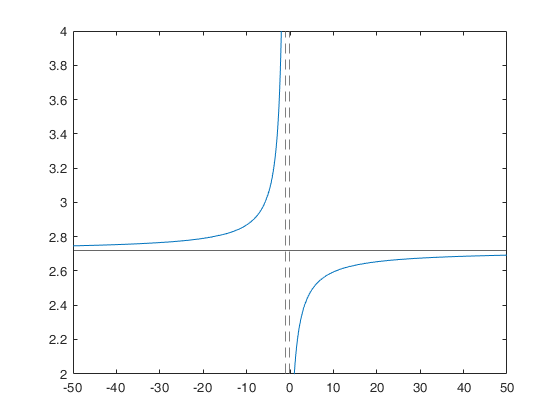

yline(exp(1)); % 渐近线

#### EX 5-6 导数


$$f=2x^4 +x\;\;\;\textrm{求：}\;f^{\prime } \;\textrm{f"}$$


clear;
syms x a
f = 2*x^4+x

$$f = 2\,x^{4}+x$$

% 一阶导数
diffx1 = diff(f,x)

$$diffx1 = 8\,x^{3}+1$$

% 二阶导数
diffx2 = diff(f,x,2)

$$diffx2 = 24\,x^{2}$$

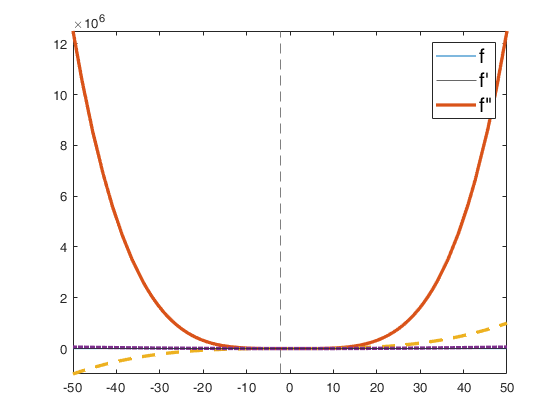

% 绘图
hold on; box on;
p(1) = fplot(f);
p(2) = fplot(diffx1,'--');
p(3) = fplot(diffx2,':');
[p.LineWidth] = deal(2.5);
l = legend('f', "f'", 'f"');
l.FontSize = 15;

#### EX 5-7 积分


$$f=ax^2 \;\;\;\textrm{求：}\;\int_{\;}^{\;} f\;\mathrm{d}\left(x\right)\;\;\mathrm{与}\;\int_{\;}^{\;} \left(\int_{\;}^{\;} f\;\mathrm{d}\left(x\right)\right)\;\mathrm{d}\left(x\right)$$


syms x a
f = a*x^2

$$f = a\,x^{2}$$

intf1 = int(f,x)

$$intf1 = \frac{a\,x^{3}}{3}$$

intf2 = int(int(f,x),x)

$$intf2 = \frac{a\,x^{4}}{12}$$


$$f=ax^2 \;\;\;\textrm{求：}\int_{0\;}^{1\;} f\;\mathrm{d}\left(x\right)\;\;$$


intf = int(f,x,0,1)

$$intf = \frac{a}{3}$$

#### EX 5-8 泰勒展开


$$\textrm{展开：}\;f=\sin \left(x\right)\;\;$$


clear;figure;
syms x
f = sin(x)

$$f = \sin\left(x\right)$$

f1 = taylor(f,x,0,'order',3)

$$f1 = x$$

f2 = taylor(f,x,0,'order',5)

$$f2 = x-\frac{x^{3}}{6}$$

f3 = taylor(f,x,0,'order',7)

$$f3 = \frac{x^{5}}{120}-\frac{x^{3}}{6}+x$$

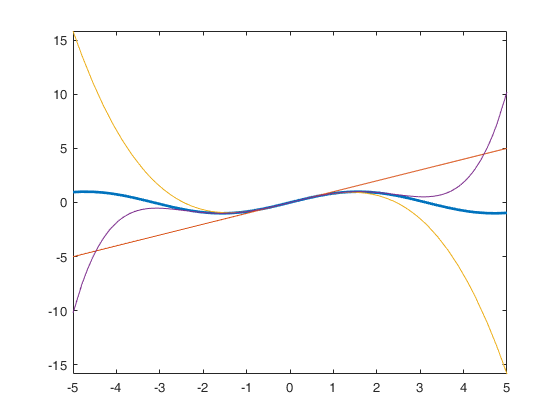

% 作图
fplot(f,'LineWidth',2); hold on;
fplot(f1); fplot(f2); fplot(f3);

#### EX 5-9 傅立叶展开

clear;figure;
syms x
f = abs(x)/x; % 构造一个方波
p = 10; % 设置展开项数
L = pi; % 原函数半周期
fs=int(f,x,-L,L)/L/2;
for n=1:p
    a=int(f*cos(n*pi*x/L),x,-L,L)/L;
    b=int(f*sin(n*pi*x/L),x,-L,L)/L;
    fs=fs+a*cos(n*pi*x/L)+b*sin(n*pi*x/L);
end
fs % 显示傅立叶展开结果

$$fs = \frac{4\,\sin\left(3\,x\right)}{3\,\pi }+\frac{4\,\sin\left(5\,x\right)}{5\,\pi }+\frac{4\,\sin\left(7\,x\right)}{7\,\pi }+\frac{4\,\sin\left(9\,x\right)}{9\,\pi }+\frac{4\,\sin\left(x\right)}{\pi }$$

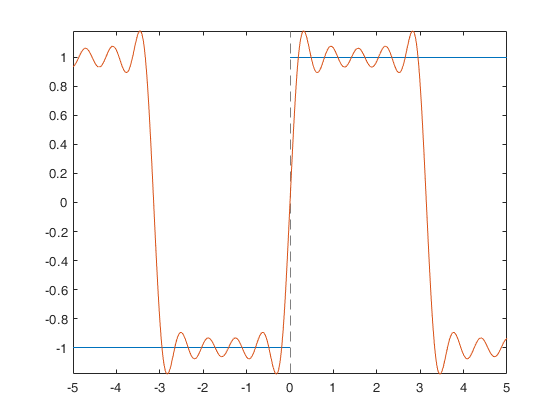

fplot(f);hold on;
fplot(fs);

#### EX 5-10 一维插值

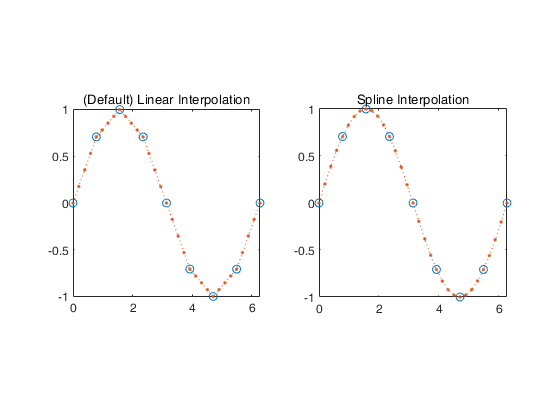

clear;figure;
x = 0:pi/4:2*pi; 
v = sin(x); % 定义已知数据点
xq = 0:pi/16:2*pi; % 定义将查询点（更精细）
% 默认线性插值
ax(1) = subplot(1,2,1);
vq1 = interp1(x,v,xq);
plot(x,v,'o',xq,vq1,':.');
title('(Default) Linear Interpolation');
% 三次样条插值
ax(2) = subplot(1,2,2);
vq2 = interp1(x,v,xq,'spline');
plot(x,v,'o',xq,vq2,':.');
title('Spline Interpolation');
axis(ax, "square")

#### EX 5-11 二维网格数据插值

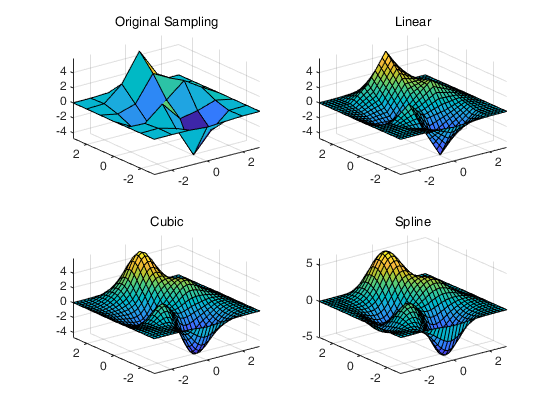

clear;figure;
[X,Y] = meshgrid(-3:3);
V = peaks(X,Y);
subplot(2,2,1);
surf(X,Y,V)
title('Original Sampling');
[Xq,Yq] = meshgrid(-3:0.2:3);
%
Vq = interp2(X,Y,V,Xq,Yq);
subplot(2,2,2);
surf(Xq,Yq,Vq);
title('Linear');
%
Vq = interp2(X,Y,V,Xq,Yq,'cubic');
subplot(2,2,3);
surf(Xq,Yq,Vq);
title('Cubic');
%
Vq = interp2(X,Y,V,Xq,Yq,'spline');
subplot(2,2,4);
surf(Xq,Yq,Vq);
title('Spline');

#### EX 5-12 二维一般数据插值

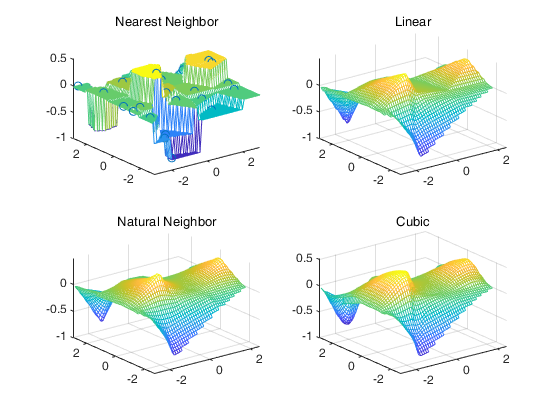

clear;figure;
x = -3 + 6*rand(30,1);
y = -3 + 6*rand(30,1);
v = sin(x).^4 .* cos(y); % 构造已知数据
[xq,yq] = meshgrid(-3:0.1:3); % 构造插值网
subplot(2,2,1);
z1 = griddata(x,y,v,xq,yq,'nearest');
plot3(x,y,v,'o'); hold on
mesh(xq,yq,z1)
title('Nearest Neighbor')
subplot(2,2,2);
z2 = griddata(x,y,v,xq,yq,'linear');
plot3(x,y,v,'o'); mesh(xq,yq,z2)
title('Linear')
subplot(2,2,3);
z3 = griddata(x,y,v,xq,yq,'natural');
plot3(x,y,v,'o'); mesh(xq,yq,z3)
title('Natural Neighbor')
subplot(2,2,4);
z4 = griddata(x,y,v,xq,yq,'cubic');
plot3(x,y,v,'o'); mesh(xq,yq,z4)
title('Cubic')

#### EX 5-13  多项式拟合

clear;figure;
% 准备样本数据并作图
x = linspace(0,1,5);
y = 1./(1+x); 
plot(x,y,'o'); hold on
% 原始函数图像
fplot(@(x) 1./(1+x),[-0.5 2],'--')
% 拟合4次多项式并作图
p = polyfit(x,y,4) 

p =     0.1524   -0.5333    0.8667   -0.9857    1.0000


% 按三位精度显示多项式
fitFunc = poly2sym(vpa(p,3)) 

$$fitFunc = 0.15238095238237292505800724029541\,x^{4}-0.53333333334012422710657119750977\,x^{3}+0.86666666666860692203044891357422\,x^{2}-0.9857142857072176411747932434082\,x+1.0$$

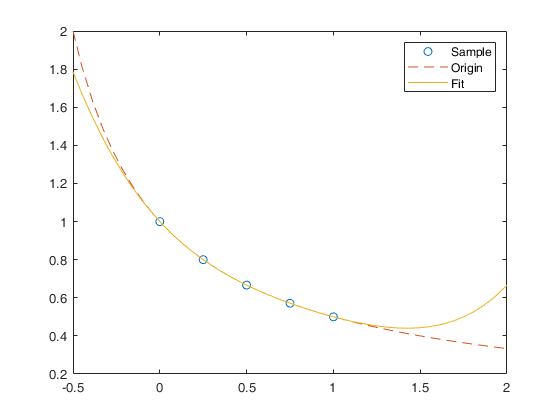

fplot(poly2sym(p),[-0.5 2])
legend('Sample','Origin','Fit')

#### EX 5-14  最小二乘拟合


$$f\left(x\right)=\frac{a_1 }{a_2 +a_3 x}$$


clear;figure;
% 准备样本数据并作图
x = linspace(0,1,5);
y = 1./(2+3*x); 
plot(x,y,'o'); hold on
% 原始函数图像
fplot(@(x) 1./(2+3*x),[-0.5 2],'--')
% 定义原型函数
func = @(a,x) a(1)./(a(2)+a(3)*x)

func = 包含以下值的 function_handle :
    @(a,x)a(1)./(a(2)+a(3)*x)


% 最小二乘拟合
a = lsqcurvefit(func, [1 1 1], x, y)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


a =     3.2783    6.5565    9.8348


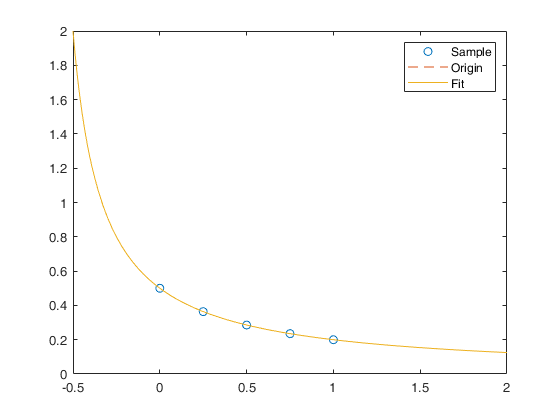

% 作图 - 系数a已知
fplot(@(x) a(1)./(a(2)+a(3)*x),[-0.5 2])
legend('Sample','Origin','Fit')

#### EX 5-15  代数方程

解一元方程：$x^2 +x-1=0$

syms x
eqn = x^2+x-1 % 方程定义

$$eqn = x^{2}+x-1$$

solveSym1 = solve(eqn,x) % 解析解

$$solveSym1 = \left(\begin{array}{c} -\frac{\sqrt{5}}{2}-\frac{1}{2}\\ \frac{\sqrt{5}}{2}-\frac{1}{2} \end{array}\right)$$

solveNum1 = vpasolve(eqn) % 数值解

$$solveNum1 = \left(\begin{array}{c} -1.6180339887498948482045868343656\\ 0.61803398874989484820458683436564 \end{array}\right)$$

解多元方程：$\left\lbrace \begin{array}{cc}
x+y=0 & \;\\
x^2 +y^2 =1 & \;
\end{array}\right.$

syms x y
eqn1 = x+y, eqn2 = x^2+y^2-1 % 方程定义

$$eqn1 = x+y$$

$$eqn2 = x^{2}+y^{2}-1$$

[xs,ys] = solve(eqn1,eqn2) % 解析解

$$xs = \left(\begin{array}{c} \frac{\sqrt{2}}{2}\\ -\frac{\sqrt{2}}{2} \end{array}\right)$$

$$ys = \left(\begin{array}{c} -\frac{\sqrt{2}}{2}\\ \frac{\sqrt{2}}{2} \end{array}\right)$$

[xn,yn] = vpasolve(eqn1,eqn2) % 数值解

$$xn = \left(\begin{array}{c} 0.70710678118654752440084436210485\\ -0.70710678118654752440084436210485 \end{array}\right)$$

$$yn = \left(\begin{array}{c} -0.70710678118654752440084436210485\\ 0.70710678118654752440084436210485 \end{array}\right)$$

#### EX 5-16  无约束优化问题

$f\left(x\right)=100{\left(x_2 -{x_1 }^2 \right)}^2 +{\left(1-x_1 \right)}^2$  求：$\min_x \;f\left(x\right)$

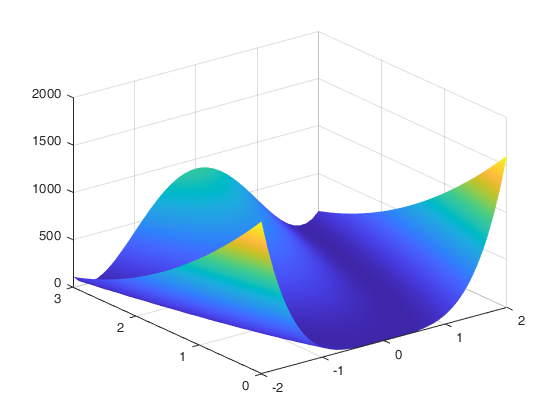

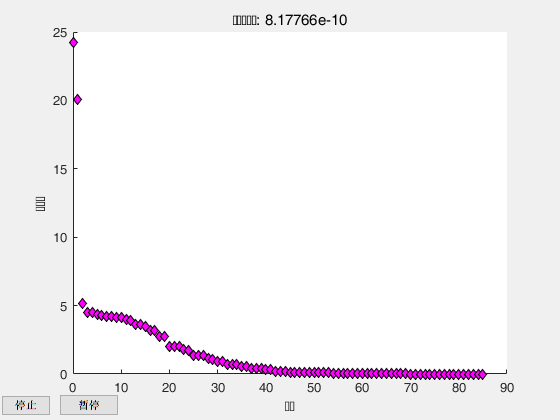

x1 =     1.0000    1.0000


clear;figure;
% 作surf图-直观印象
[x,y]=meshgrid(-2:.1:2,0:.1:3);
z = 100*(y - x.^2).^2 + (1 - x).^2;
surf(x,y,z); 
shading interp;
% 设置函数
fun = @(x) 100*(x(2) - x(1)^2)^2 + (1 - x(1))^2;
% 设置优化初值
x0 = [-1.2,1]; 
% 设置显示迭代目标函数图
options = optimset('PlotFcns',@optimplotfval);
% 方法1-MATLAB
x1 = fminsearch(fun,x0,options)

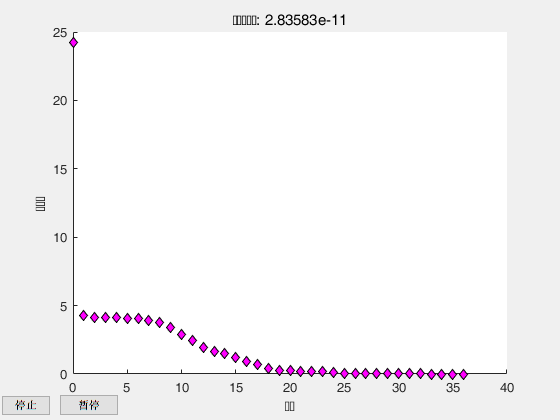


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x2 =     1.0000    1.0000


% 方法2-优化工具箱
x2 = fminunc(fun,x0,options)

#### EX 5-17  边界约束优化——线性规划

$f\left(x\right)=-2x_1 -x_2$  其中：$2x_2 \le 7;{\;x}_1 +4x_2 \le 9;\;x_1 \le 4;\;x_2 \le 8$

求：$\min_x \;f\left(x\right)$

f = [2 1]'; % 函数定义
A = [0 2; 1 4]; b = [7; 9];
Aeq = []; beq = [];
lb = []; ub = [4; 8];
[x, fval] = linprog(f,A,b,Aeq,beq,lb,ub)


Problem is unbounded.


x =

     []


fval =

     []



#### EX 5-18  边界约束优化——非线性规划

$f\left(x\right)=-x_1 x_2 x_3$  其中：$0\le x_1 +2x_2 +4x_3 \le 12$求：$\min_x \;f\left(x\right)$

% 不等式约束
func = @(x) -x(1)*x(2)*x(3);
x0 = [1; 1; 1];
A = [-1 -2 -4; 1 2 4];
b = [0; 12];
[x1, val1] = fmincon(func, x0, A, b)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x1 =     4.0000
    2.0000
    1.0000


val1 = -8.0000

$f\left(x\right)=-x_1 x_2 x_3$  其中：$x_1 +2x_2 +4x_3 =24$求：$\min_x \;f\left(x\right)$

% 等式约束
func = @(x) -x(1)*x(2)*x(3);
x0 = [1; 1; 1];
A = [1 2 4];
b = 24;
[x2, val2] = fmincon(func, x0, [], [], A, b)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x2 =     8.0000
    4.0000
    2.0000


val2 = -64.0000

#### EX 5-19  `最大值最小化问题`

$f\left(x\right)=\left\lbrack \begin{array}{c}
-x_1 x_2 x_3 \\
x_1 {-x}_2 {+x}_3 
\end{array}\right\rbrack$  其中：$0\le x_1 +2x_2 +4x_3 \le 12$求：$\min_x \underset{i}{\;\max } \;f_i \left(x\right)$

% 不等式约束
func = @(x) [-x(1)*x(2)*x(3); x(1)-x(2)+x(3)];
x0 = [1; 1; 1];
A = [-1 -2 -4; 1 2 4];
b = [0; 12];
[x1, val1] = fminimax(func, x0, A, b)


Local minimum possible. Constraints satisfied.

fminimax stopped because the predicted change in the objective function
is less than the value of the function tolerance and constraints 
are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x1 =     1.1786
    4.3726
    0.5191


val1 =    -2.6749
   -2.6749


#### EX 5-20 常微分方程解析解

1. 无初始条件微分方程


$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }y=\textrm{ay}$$


syms a t y(t) z(t)
eqn = diff(y,t,2) == a*y % 符号方程

$$eqn(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=a\,y\left(t\right)$$

ySol(t) = dsolve(eqn)

$$ySol(t) = C_{1}\,{\mathrm{e}}^{-\sqrt{a}\,t}+C_{2}\,{\mathrm{e}}^{\sqrt{a}\,t}$$

2. 有初始条件的微分方程


$$\frac{\mathrm{d}\;y}{\mathrm{d}\;t}\;=\;\textrm{ay}$$
 
$$y\left(0\right)=5$$


eqn = diff(y,t) == a*y % 符号方程

$$eqn(t) = \frac{\partial }{\partial t}y\left(t\right)=a\,y\left(t\right)$$

cond = y(0) == 5; % 初始条件
ySol(t) = dsolve(eqn,cond)

$$ySol(t) = 5\,{\mathrm{e}}^{a\,t}$$

3. 微分方程组


$$\left\lbrace \begin{array}{cc}
\frac{\mathrm{d}\;y}{\mathrm{d}\;t}\;=z & \;\\
\frac{\mathrm{d}\;z}{\mathrm{d}\;t}\;=-y & \;
\end{array}\right.$$
 

eqns = [diff(y,t) == z, diff(z,t) == -y]

$$eqns(t) = \left(\begin{array}{cc} \frac{\partial }{\partial t}y\left(t\right)=z\left(t\right) & \frac{\partial }{\partial t}z\left(t\right)=-y\left(t\right) \end{array}\right)$$

sol = dsolve(eqns); 
solY = sol.y, solZ = sol.z

$$solY = C_{1}\,\cos\left(t\right)+C_{2}\,\sin\left(t\right)$$

$$solZ = C_{2}\,\cos\left(t\right)-C_{1}\,\sin\left(t\right)$$

#### EX 5-21 常微分方程数值解

1. 一个分量的微分方程


$$y^{\prime } =2t$$


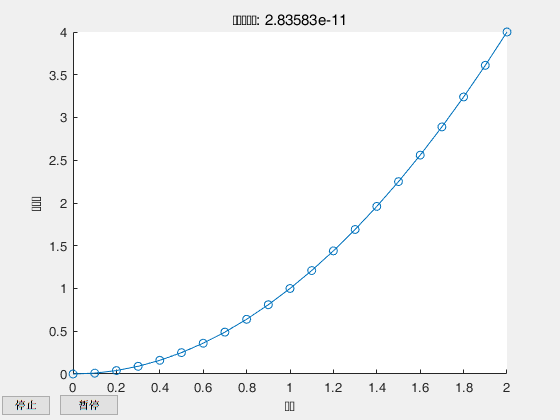

tspan = 0:0.1:2; % 求解范围
y0 = 0; % 初值条件
[t,y] = ode45(@(t,y) 2*t, tspan, y0);
plot(t,y,'-o')

2. 微分方程组


$$\left\lbrace \begin{array}{cc}
{y_1 }^{\prime } =y_2  & \;\\
{y_2 }^{\prime } ={\left(1-y_1^2 \right)y}_2 -y_1  & \;
\end{array}\right.$$


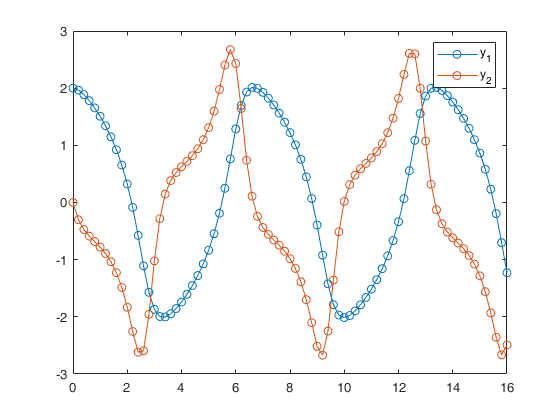

clear;figure;
f = @(t,y) [y(2); (1-y(1)^2)*y(2)-y(1)];
[t,y] = ode45(f, 0:0.2:16,[2; 0]);
plot(t,y(:,1),'-o',t,y(:,2),'-o')
legend('y_1','y_2')

#### EX 5-22 偏微分方程数值解

方程：$\pi^2 \;\frac{\partial }{\partial t}u=\frac{\partial }{\partial x}\left(\frac{\partial }{\partial x}u\right)\;$

方程区间：$x\in \left\lbrack 0,1\right\rbrack ,\;t\in \left\lbrack 0,\infty \right\rbrack$

初始条件：$u\left(x,0\right)=\sin \;\pi x$

边界条件：$u\left(0,t\right)\equiv 0,\;\pi e^{-t} +\frac{\partial }{\partial x}u\left(1,t\right)=0$

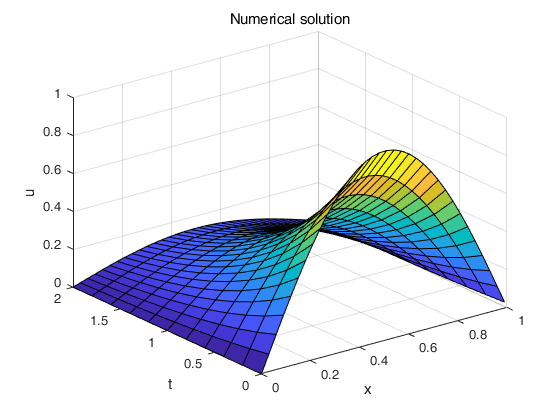

clear;figure;
m = 0; x=0:0.03:1; t=0:0.2:2;
u = pdepe(m,@pdeeqn,@pdeic,@pdebc,x,t);
surf(x,t,u); title('Numerical solution')
xlabel('x'); ylabel('t'); zlabel('u');

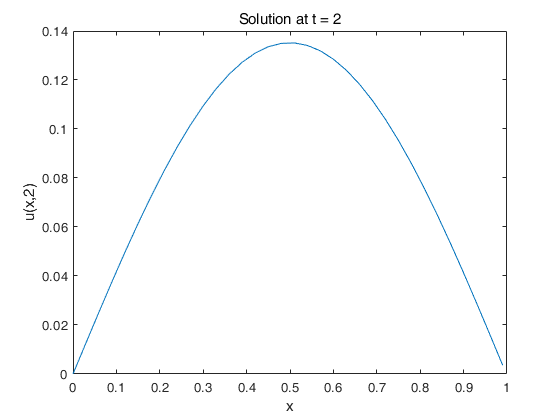

plot(x,u(end,:)); title('Solution at t = 2')
xlabel('x'); ylabel('u(x,2)')

#### EX 5-23 概率分布与概率密度

1. 泊松分布（离散）

x=0:20; lamda=10;
pdf_P=pdf('Poisson',x,lamda);
cdf_P=cdf('Poisson',x,lamda);
ax(1)=subplot(2,2,1);stem(x,pdf_P),line(x,pdf_P);
title('Poisson PDF');
ax(2)=subplot(2,2,2);plot(x,cdf_P);
title('Poisson CDF');

2. 正态分布（连续）

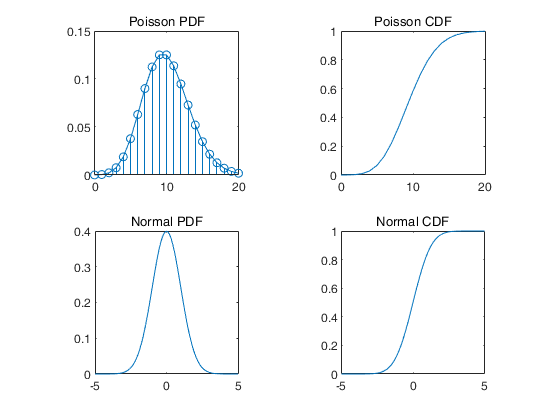

x=-5:0.02:5; mu=0; sigma=sqrt(1);
pdf_N=pdf('Normal',x,mu,sigma);
cdf_N=cdf('Normal',x,mu,sigma);
ax(3)=subplot(2,2,3);plot(x,pdf_N);
title('Normal PDF');
ax(4)=subplot(2,2,4);plot(x,cdf_N);
title('Normal CDF');
axis(ax,"square")

#### EX 5-24 伪随机数

1. 均匀分布和正态分布

ax(1) = subplot(2,2,1); 
histogram(rand(1e4,1),20);
ax(2) = subplot(2,2,2); 
histogram(randn(1e4,1),20);

2. 指数分布和卡方分布

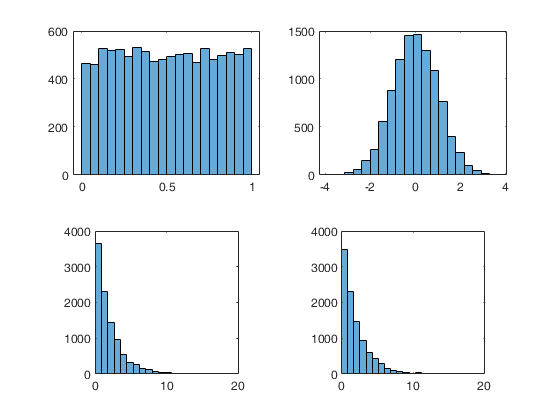

ax(1) = subplot(2,2,3); 
histogram(random('Exponential', 2, [1e4 1]),20);
ax(2) = subplot(2,2,4); 
histogram(random('Chisquare', 2, [1e4 1]),20);
axis(ax,'square')

#### EX 5-25 `统计量分析`

1. 均值、方差、标准差

clear;
% 构造概率分布随机数
x = random('Normal',2,4,[1e4,1]);
meanX = mean(x) % 均值

meanX = 1.9779

s2X = var(x) % 方差

s2X = 15.8127

sX = std(x) % 标准差

sX = 3.9765

% 构造概率分布对象
pd = makedist('Normal','mu',2,'sigma',4); 
meanX2 = pd.mean % 均值

meanX2 = 2

meanX2_mu = pd.mu % 均值

meanX2_mu = 2

s2X2 = pd.var % 均值

s2X2 = 16

sX2 = pd.std % 标准差

sX2 = 4

sX2_sigma = pd.sigma % 标准差

sX2_sigma = 4

2. 原点矩与中心矩

A1 = sum(x.^1)/length(x) % 一阶原点矩

A1 = 1.9779

A2 = sum(x.^2)/length(x) % 二阶原点矩

A2 = 19.7232

B1 = moment(x,1) % 一阶中心矩

B1 = 0

B2 = moment(x,2) % 二阶中心矩

B2 = 15.8111

#### EX 5-26 参数估计

clear;figure;
% 构造概率分布随机数
x = random('Normal',2,4,[1e4,1]);
% 方法1
pd = fitdist(x,'Normal')

pd =   NormalDistribution

  正态 分布
       mu = 2.00611   [1.92756, 2.08465]
    sigma = 4.00689   [3.95212, 4.06321]


% 方法2
[muHat,sigmaHat,muCI,sigmaCI] = normfit(x,0.05)

muHat = 2.0061

sigmaHat = 4.0069

muCI =     1.9276
    2.0846


sigmaCI =     3.9521
    4.0632


#### EX 5-27 `假设检验`

clear;figure;
% 构造概率分布随机数
x = random('Normal',2,4,[1e4,1]);
sX = std(x); % 标准差
% Z检验-已知标准差
[hZ,pZ,ciZ,~]= ztest(x,2,sX)

hZ = 0

pZ = 0.9547

ciZ =     1.9239
    2.0806


% T检验-不知标准差
[hT,pT,ciT,~] = ttest(x,2)

hT = 0

pT = 0.9547

ciT =     1.9239
    2.0806


#### FUNCTION-EX-5-22

方程（equation, eqn）

function [c,f,s] = pdeeqn(x,t,u,DuDx)
c = pi^2; f = DuDx; s = 0;
end

初始条件（initial condition, ic）

function u0 = pdeic(x)
u0 = sin(pi*x);
end

边界条件（boundary condition, bc）

function [pl,ql,pr,qr] = pdebc(xl,ul,xr,ur,t)
pl = ul; ql = 0; pr = pi * exp(-t); qr = 1;
end